# A Molecular Model for Intercellular Synchronization in the Mammalian Circadian Clock

## Init params

N = 100; % must be a square number
is_LD = false;

% disturb_v = 0.1;
% disturb_k = 0.2;
disturb_v = 0.1;
disturb_k = 0.2;

p_0 = init_pre_params();
v_sP0 = init_v_sP0(N, disturb_v);
p = init_params(N, disturb_k);

alpha = spatial_weight(N);
epsilon = calculate_eps(N, alpha);

y = init_y(N);

num_eq = 17;
num_param = 56;

## Options

tspan = [0 480];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);

## Simulate DD

ode_DD = @(t, y) LG_VIP_total(t, y, p_0, p, N, epsilon, alpha, v_sP0, is_LD,-1);

[t1, y1] = ode45(ode_DD, tspan, y, options);

## Visualize DD

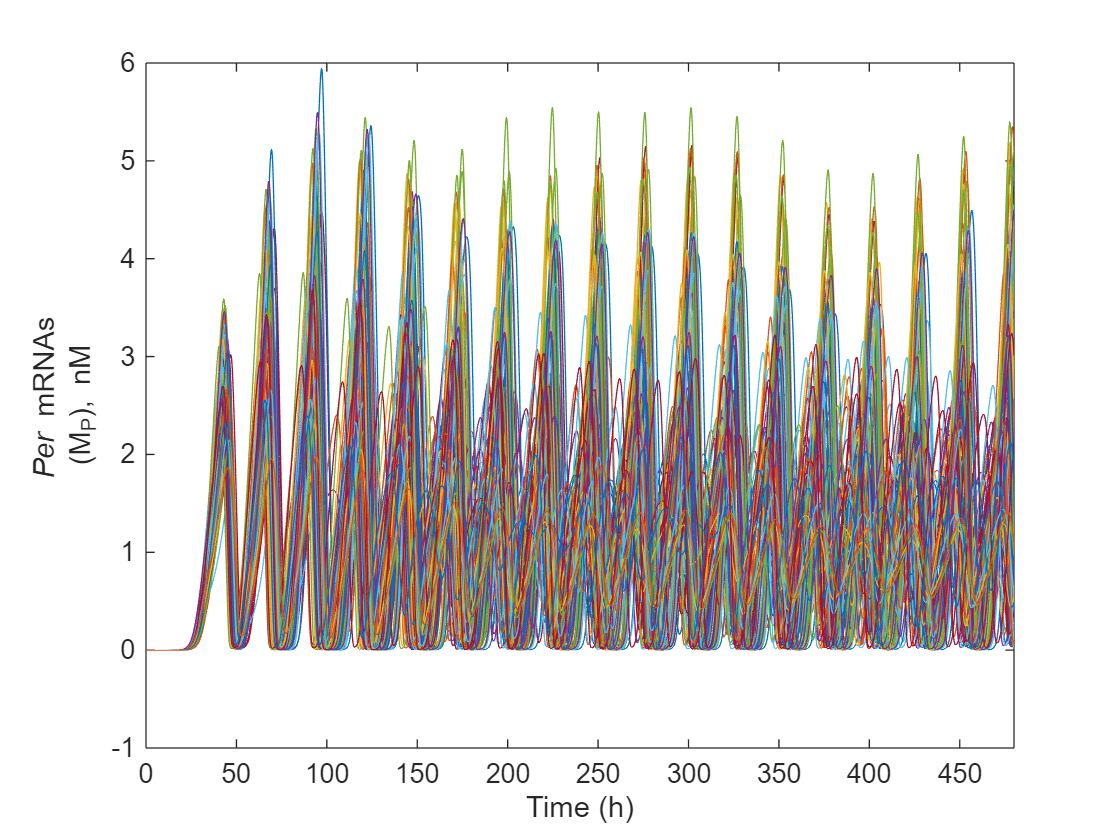

delay = 480;
M_P = y1(:, 1:num_eq:end);

figure;
plot(t1, M_P);
xlim([t1(end)-delay, t1(end)]);
xlabel('Time (h)');
ylabel({'{\it Per} mRNAs', '(M_P), nM'});

## **R and SI**

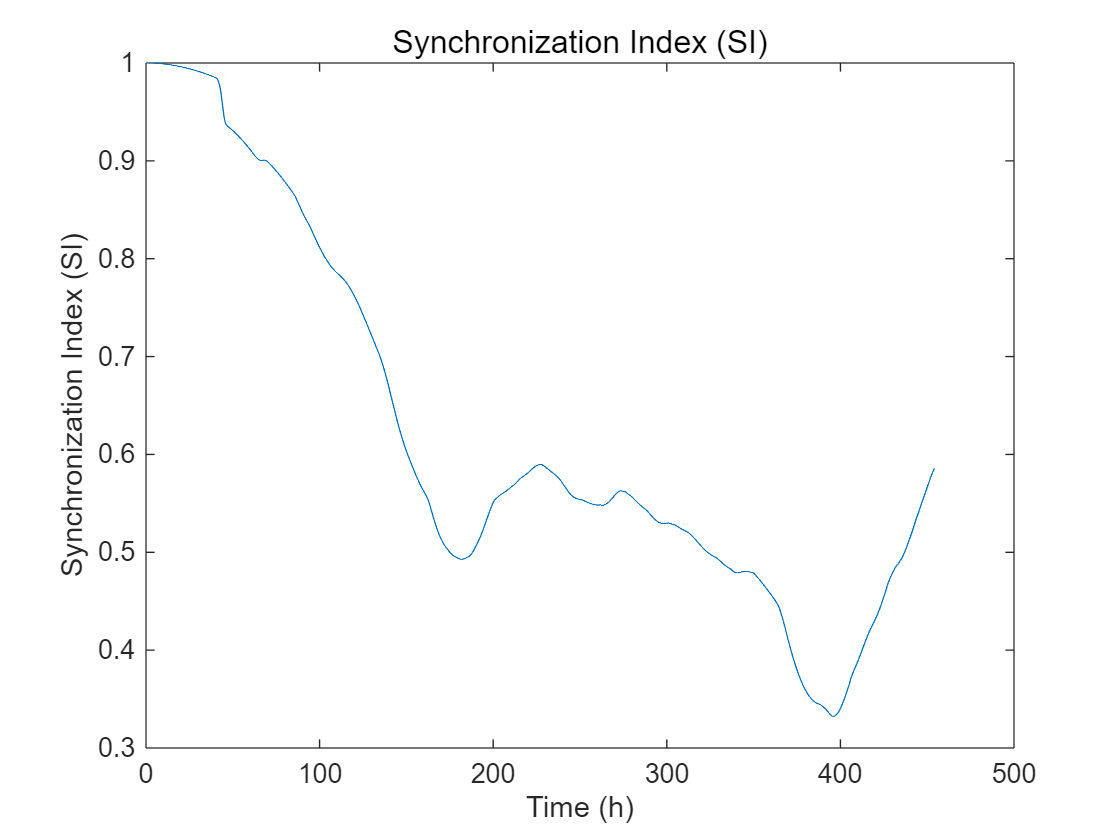

M_P = y1(:, 1:num_eq:end);
[SI_t, theta] = SI(M_P,t1);
X = y1(400:end,1:num_eq:end);
R_t = R(X,t1(400:end));
figure;
plot(t1(30:end), SI_t(30:end));
xlabel('Time (h)');
ylabel('Synchronization Index (SI)');
title(sprintf('Synchronization Index (SI)'), 'FontSize', 12);

## Period

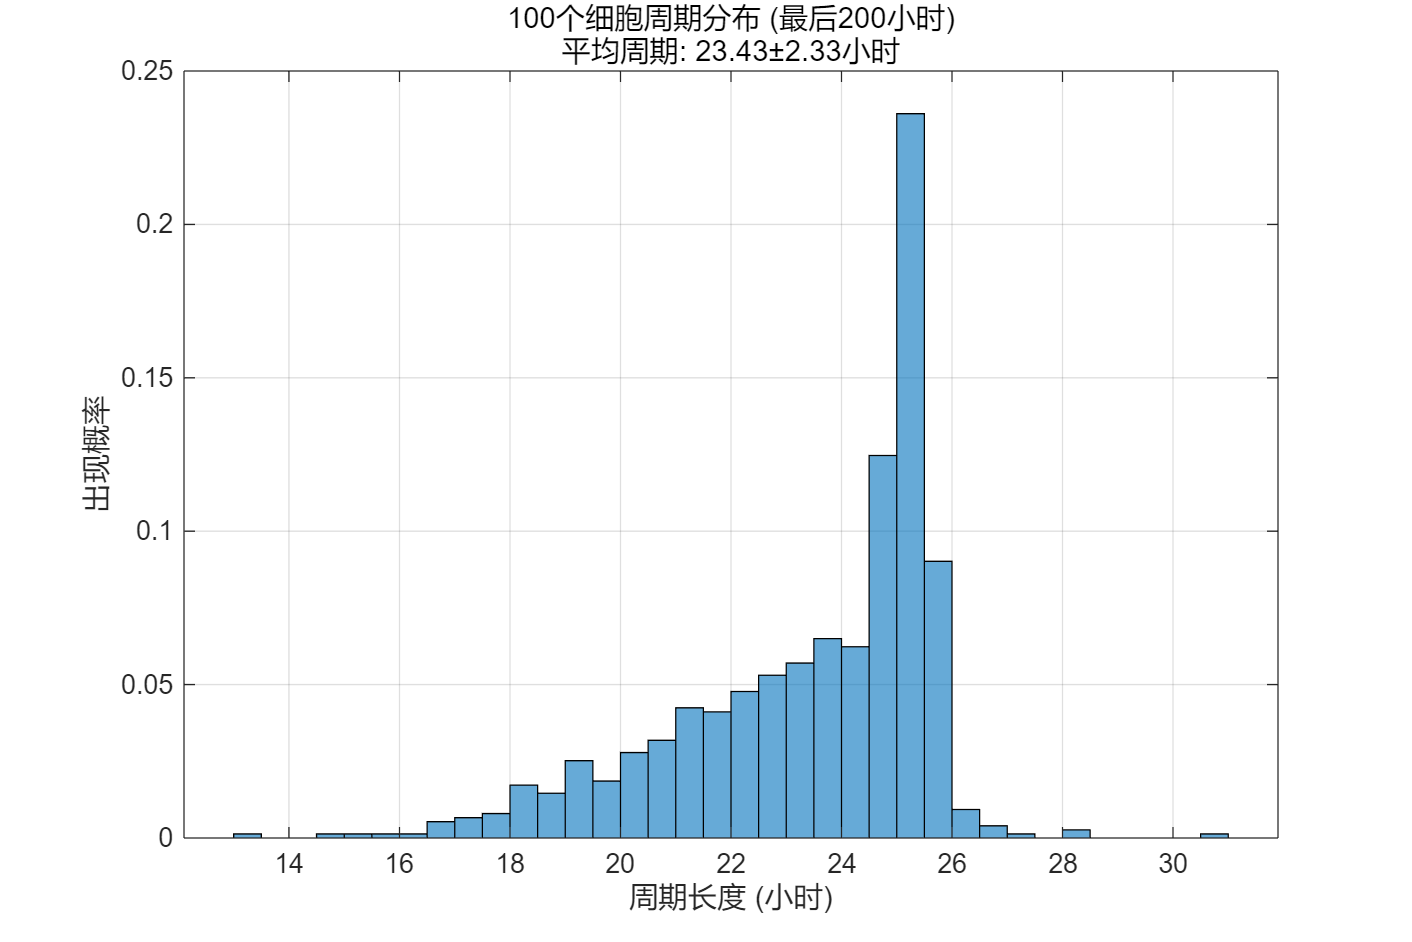

分析完成:
总周期数: 754
平均周期: 23.43 ± 2.33 小时
周期变异系数: 9.94%


t_signal = t1;
signal = y1(:,1:num_eq:end);
 
period_peak_distribution(t_signal, signal);

## 消融：240h后，关闭同步

ode_DD = @(t, y) LG_VIP_total(t, y, p_0, p, N, epsilon, alpha, v_sP0, is_LD,240);

[t1, y1] = ode45(ode_DD, tspan, y, options);

## Visualize DD

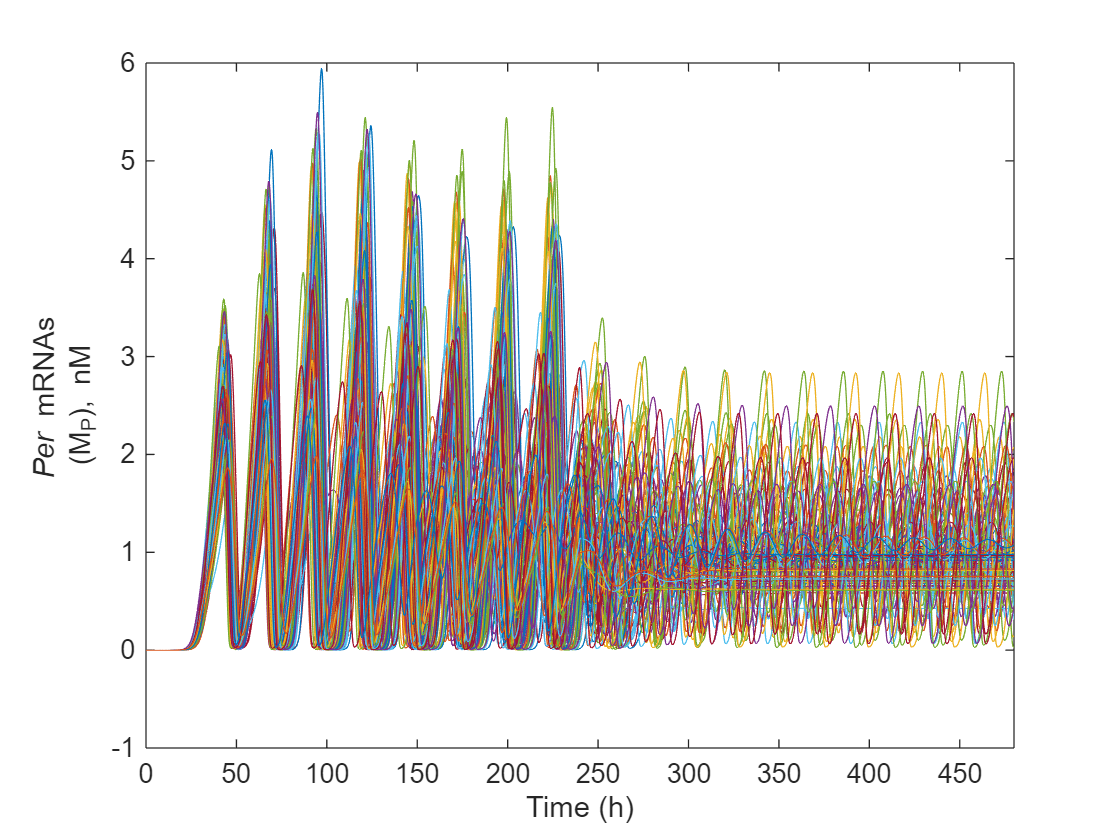

delay = 480;
M_P = y1(:, 1:num_eq:end);

figure;
plot(t1, M_P);
xlim([t1(end)-delay, t1(end)]);
xlabel('Time (h)');
ylabel({'{\it Per} mRNAs', '(M_P), nM'});

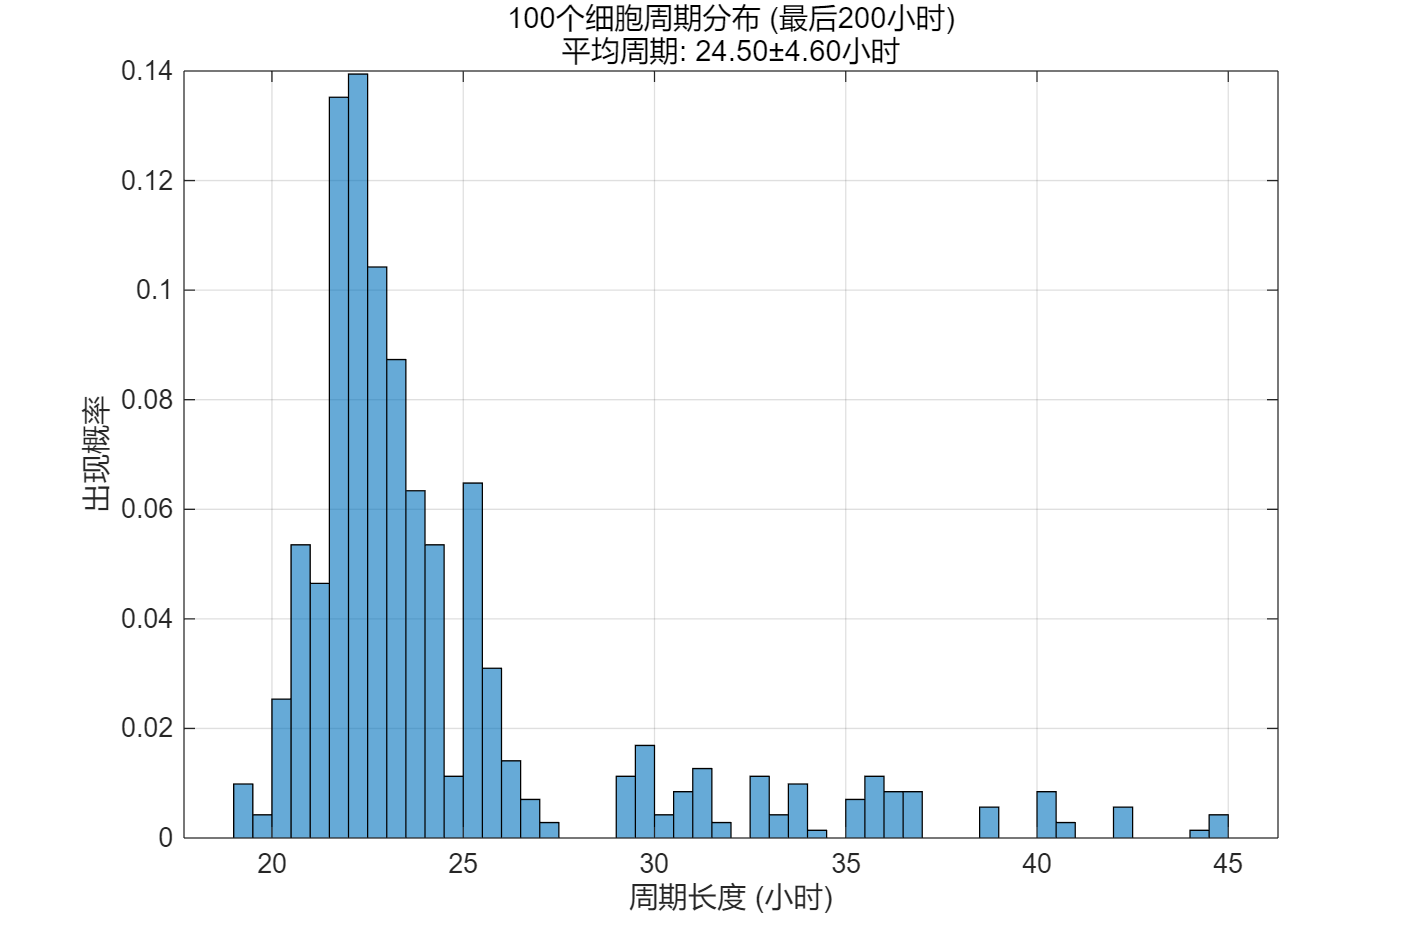

分析完成:
总周期数: 710
平均周期: 24.50 ± 4.60 小时
周期变异系数: 18.76%


t_signal = t1;
signal = y1(:,1:num_eq:end);
 
period_peak_distribution(t_signal, signal);

## **R and SI**

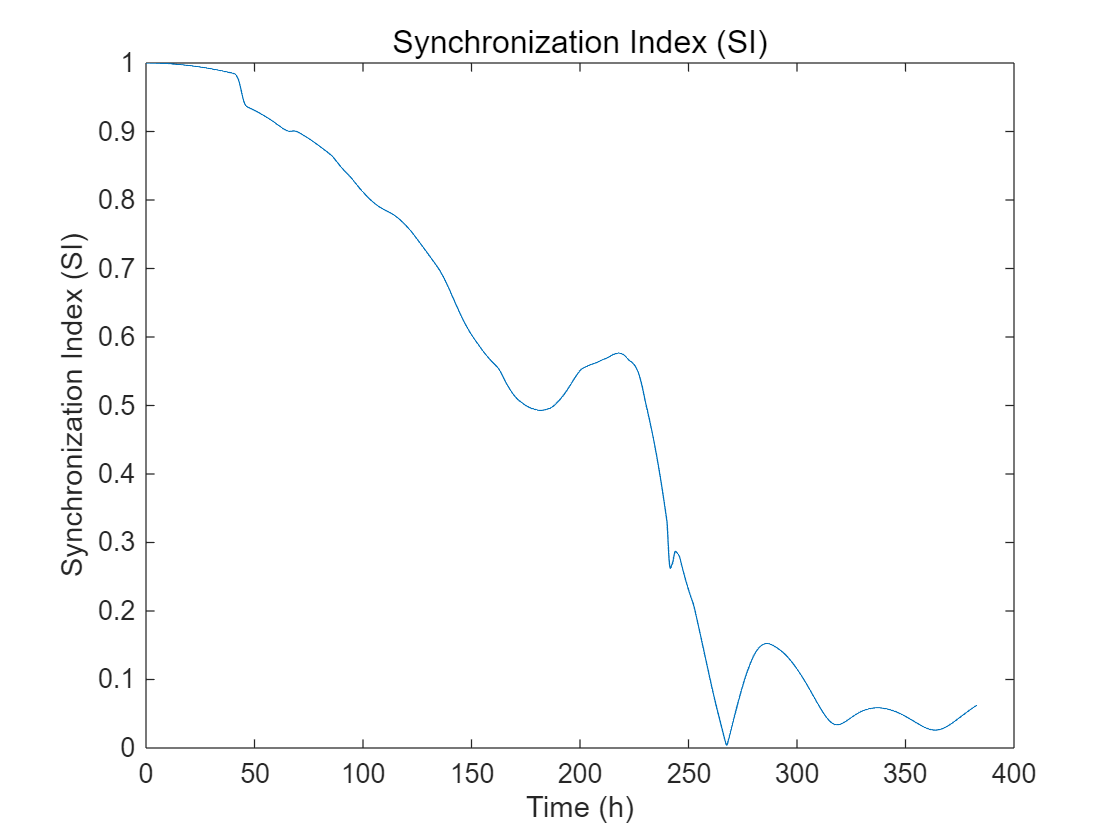

M_P = y1(:, 1:num_eq:end);
[SI_t, theta] = SI(M_P,t1);
X = y1(400:end,1:num_eq:end);
R_t = R(X,t1(400:end));
figure;
plot(t1(30:end), SI_t(30:end));
xlabel('Time (h)');
ylabel('Synchronization Index (SI)');
title(sprintf('Synchronization Index (SI)'), 'FontSize', 12);

## Simulate LD

is_LD = true;
ode_LD = @(t, y) LG_VIP_total(t, y, p_0, p, N, epsilon, alpha, v_sP0, is_LD,240);

[t2, y2] = ode45(ode_LD, tspan, y, options);

## Visualize LD

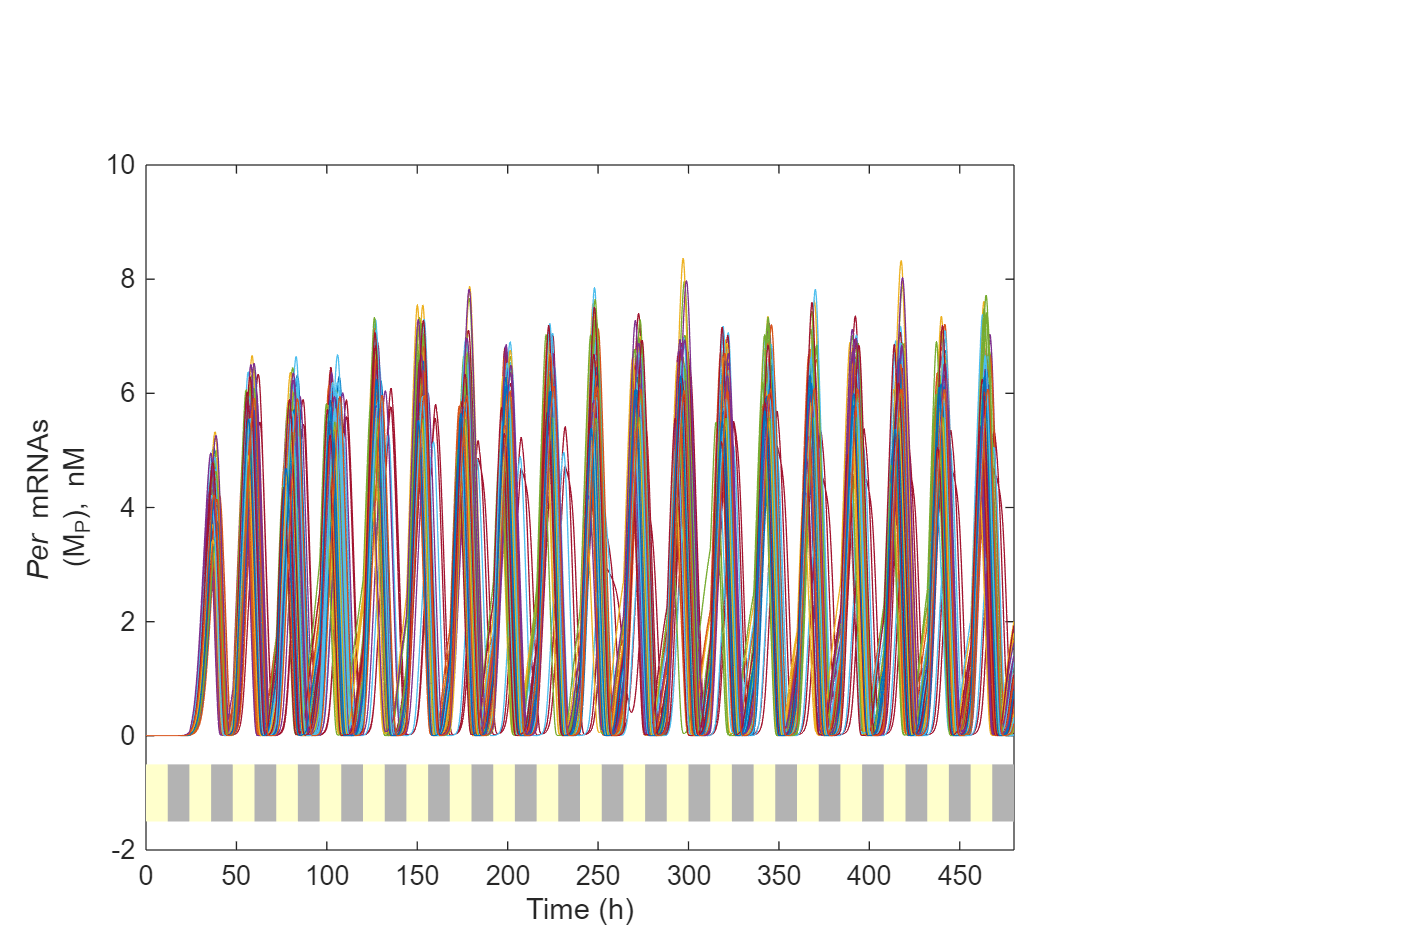

M_P = y2(:, 1:num_eq:end);

figure;
plot(t2, M_P);
xlim([t2(end)-delay, t2(end)]);
xlabel('Time (h)');
ylabel({'{\it Per} mRNAs', '(M_P), nM'});

% Get current axis limits
ax = gca;
ylims = ylim;
ypos = ylims(1) - 0.05*(ylims(2)-ylims(1)); % Position slightly below the plot

% Add light-dark indicators
start_time = t2(end) - delay;
end_time = t2(end);
for t = ceil(start_time/24)*24:24:end_time
    % Light phase (white or light yellow rectangle)
    rectangle('Position', [t, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [1 1 0.8], 'EdgeColor', 'none');
    % Dark phase (gray rectangle)
    rectangle('Position', [t+12, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none');
end

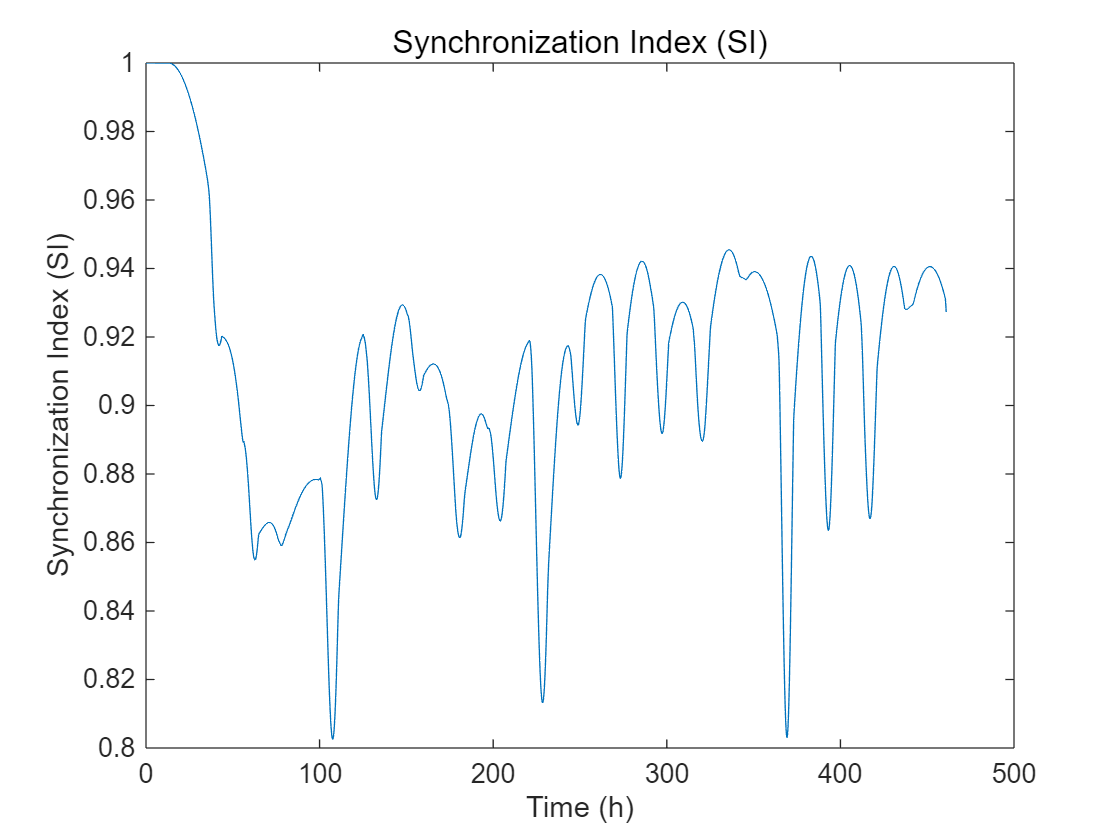

M_P = y2(:, 1:num_eq:end);
[SI_t, theta] = SI(M_P,t2);
X = y2(400:end,1:num_eq:end);
R_t = R(X,t2(400:end));
figure;
plot(t2(30:end), SI_t(30:end));
xlabel('Time (h)');
ylabel('Synchronization Index (SI)');
title(sprintf('Synchronization Index (SI)'), 'FontSize', 12);

## Period

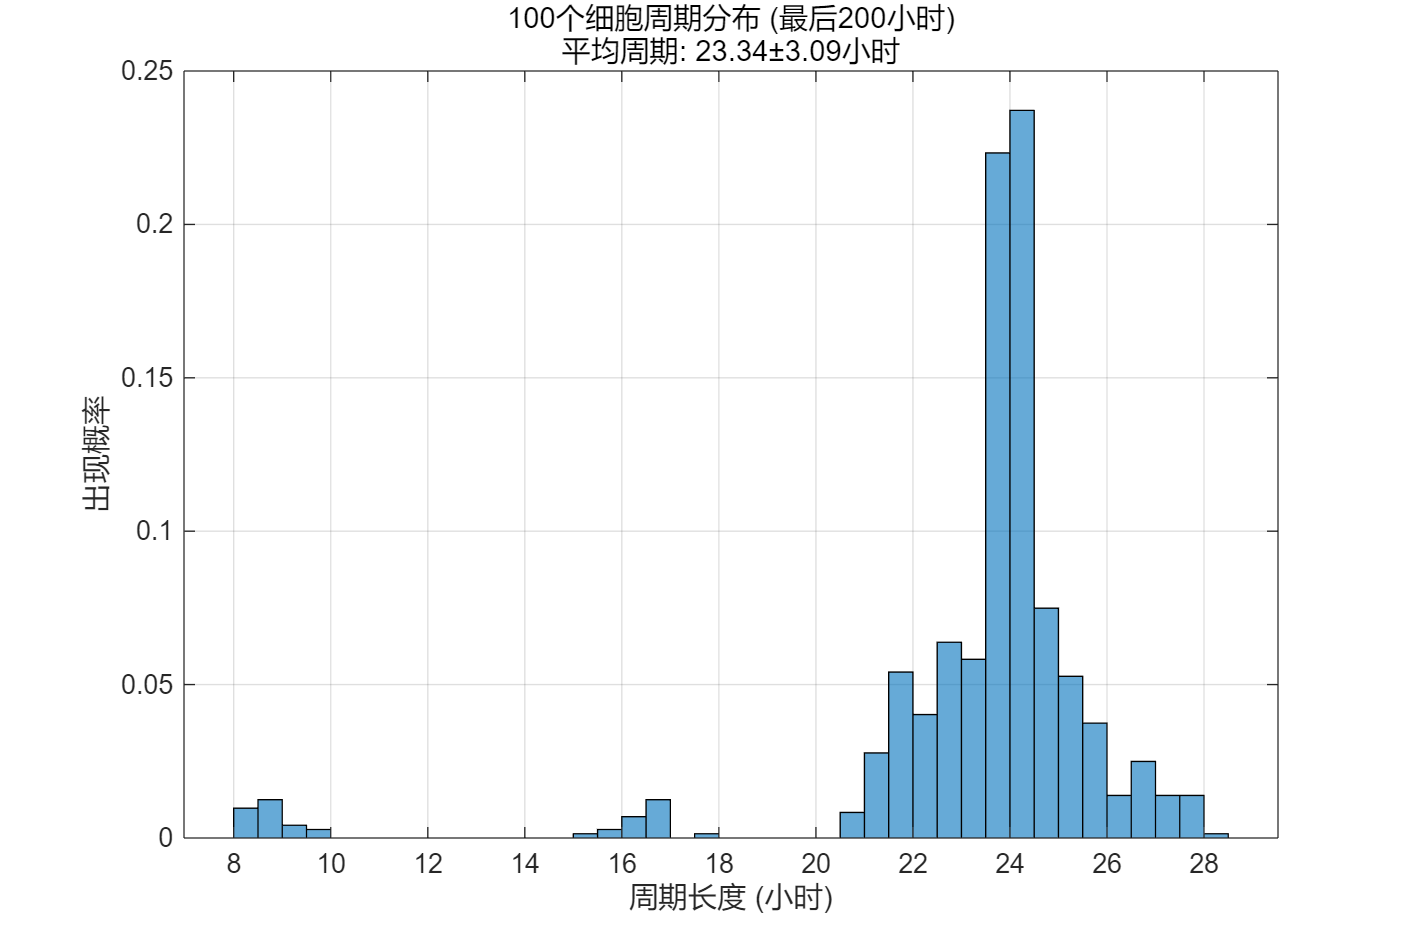

分析完成:
总周期数: 721
平均周期: 23.34 ± 3.09 小时
周期变异系数: 13.24%


t_signal = t2;
signal = y2(:,1:num_eq:end);
 
period_peak_distribution(t_signal, signal);

is_LD = true;
ode_LD = @(t, y) LG_VIP_total(t, y, p_0, p, N, epsilon, alpha, v_sP0, is_LD,-1);

[t2, y2] = ode45(ode_LD, tspan, y, options);

## Visualize LD

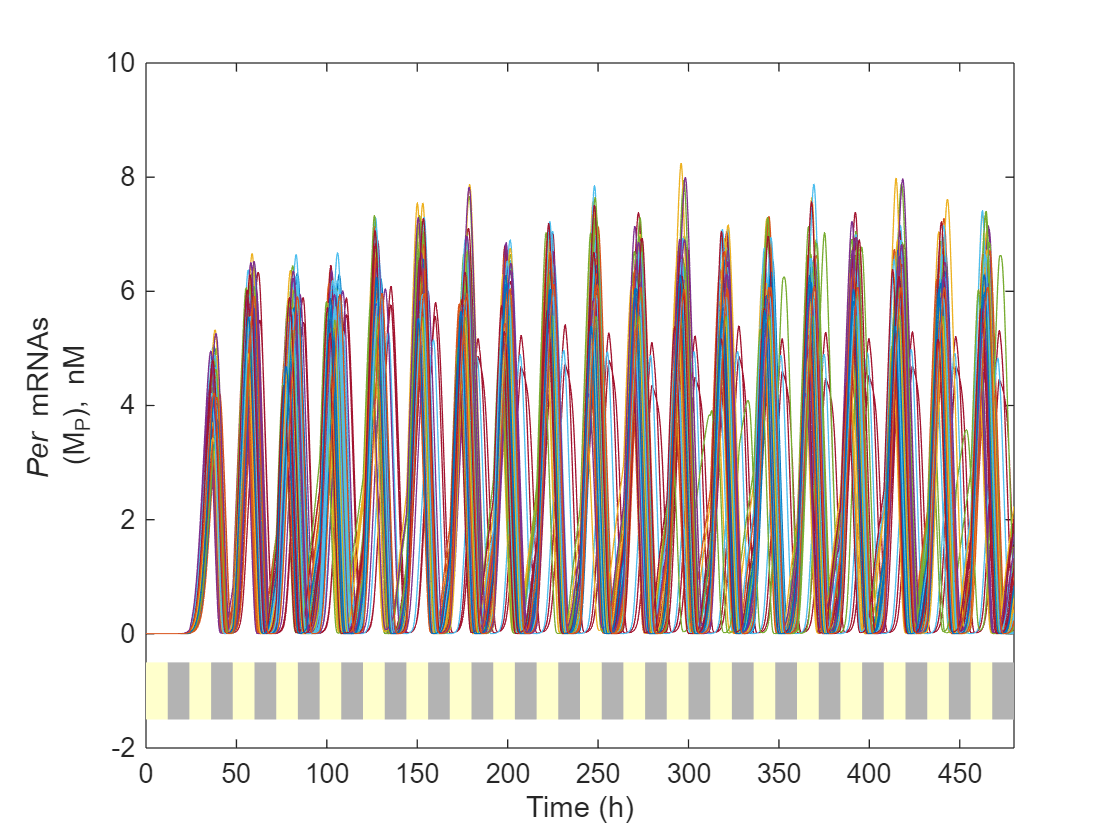

M_P = y2(:, 1:num_eq:end);

figure;
plot(t2, M_P);
xlim([t2(end)-delay, t2(end)]);
xlabel('Time (h)');
ylabel({'{\it Per} mRNAs', '(M_P), nM'});

% Get current axis limits
ax = gca;
ylims = ylim;
ypos = ylims(1) - 0.05*(ylims(2)-ylims(1)); % Position slightly below the plot

% Add light-dark indicators
start_time = t2(end) - delay;
end_time = t2(end);
for t = ceil(start_time/24)*24:24:end_time
    % Light phase (white or light yellow rectangle)
    rectangle('Position', [t, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [1 1 0.8], 'EdgeColor', 'none');
    % Dark phase (gray rectangle)
    rectangle('Position', [t+12, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none');
end

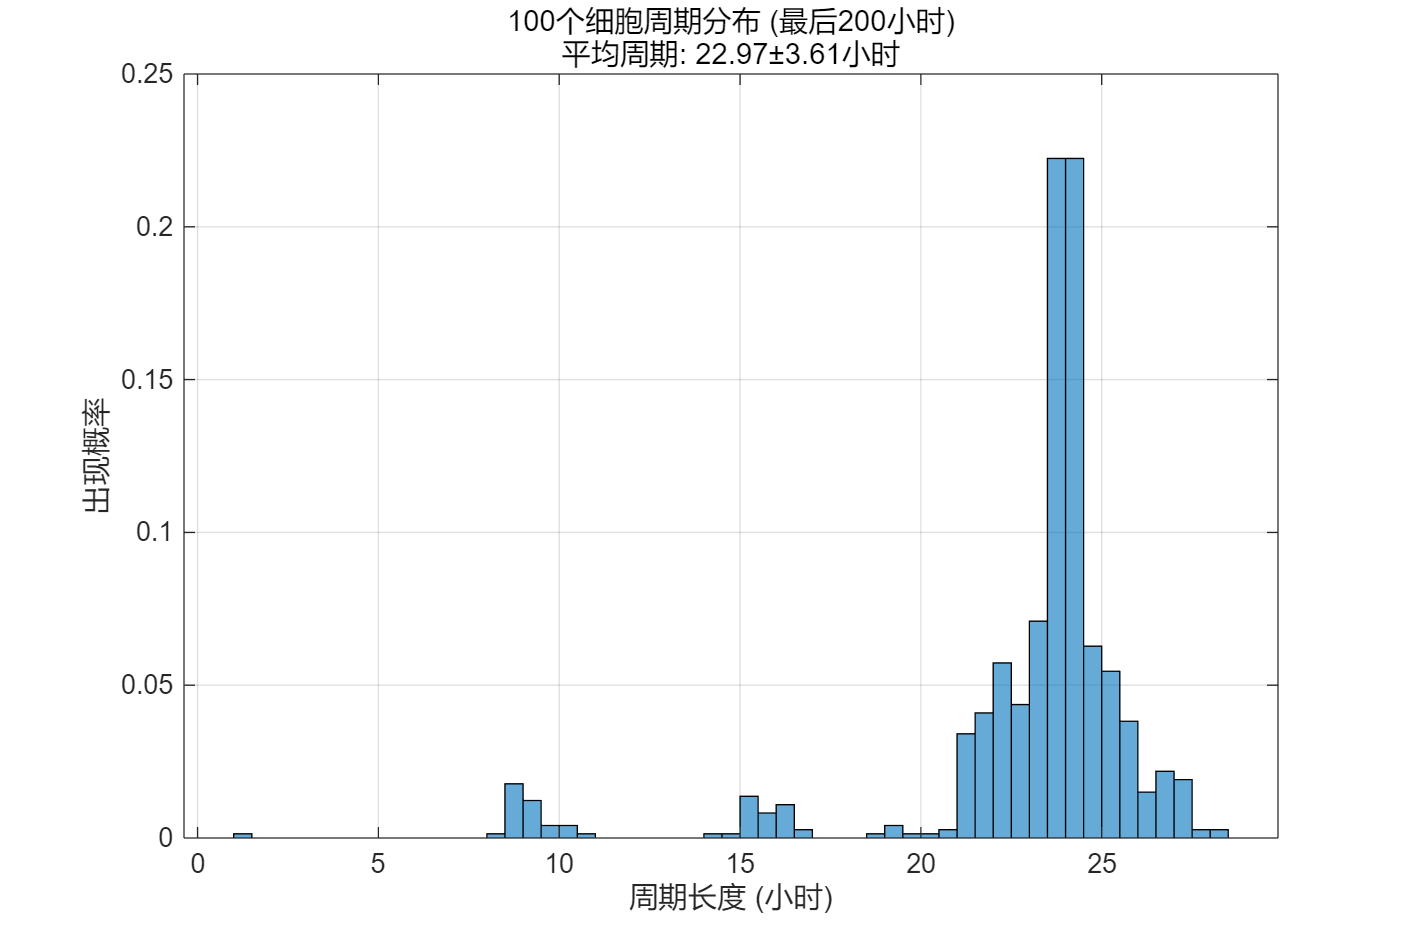

分析完成:
总周期数: 733
平均周期: 22.97 ± 3.61 小时
周期变异系数: 15.73%


t_signal = t2;
signal = y2(:,1:num_eq:end);
 
period_peak_distribution(t_signal, signal);

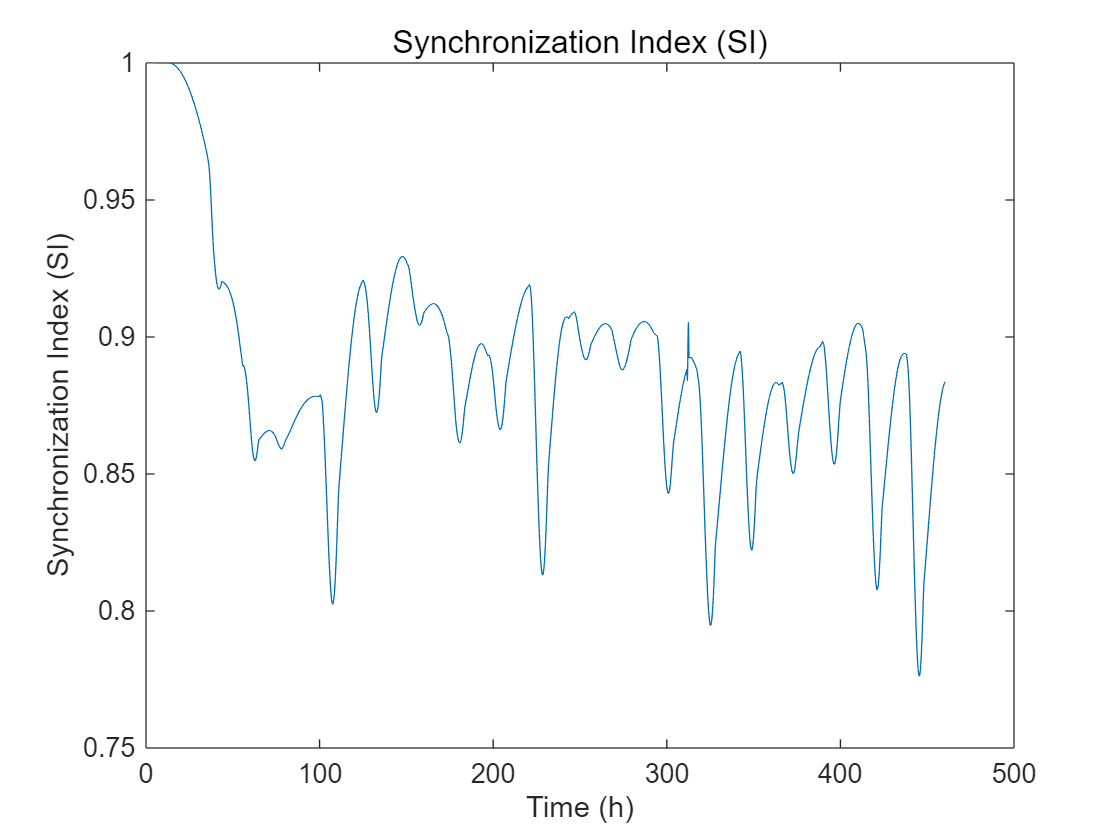

M_P = y2(:, 1:num_eq:end);
[SI_t, theta] = SI(M_P,t2);
X = y2(400:end,1:num_eq:end);
R_t = R(X,t2(400:end));
figure;
plot(t2(30:end), SI_t(30:end));
xlabel('Time (h)');
ylabel('Synchronization Index (SI)');
title(sprintf('Synchronization Index (SI)'), 'FontSize', 12);